afin1 = abs(fin1(1:257,:));
lfin1 = log(abs(fin1(1:257,:))+0.0001);

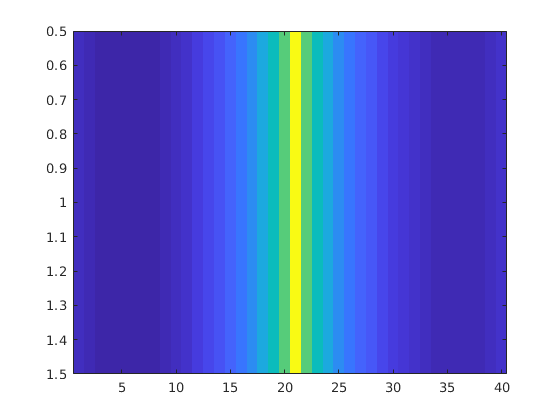

kn = ones(1, 40);
%kn(2,5) = 1;
[dfin1, k] = deconvblind(afin1, kn, 2);
imagesc(k)

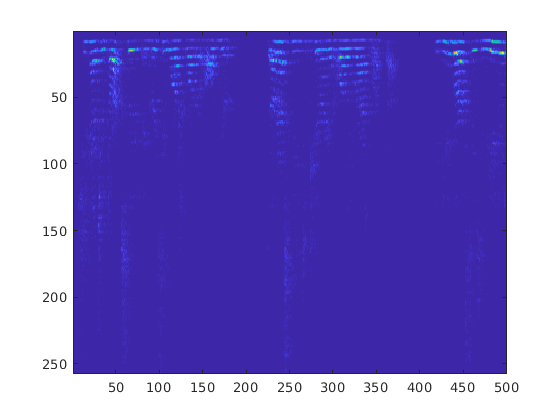

imagesc(dfin1)

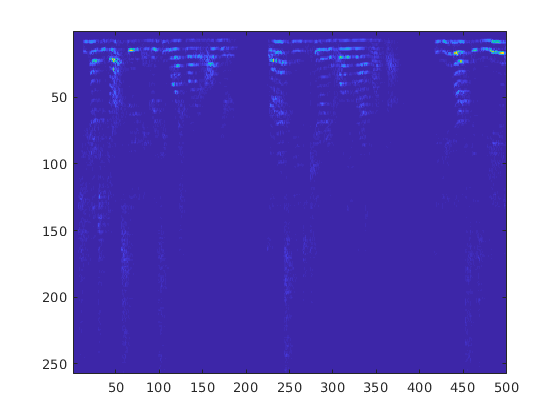

dyfin1 = deconvlucy(afin1,k,1);
imagesc(dyfin1)

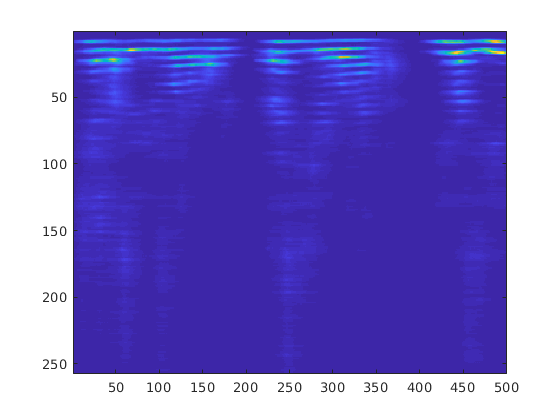

cdyfin1 = conv2(dyfin1,k,'same');
imagesc(cdyfin1)

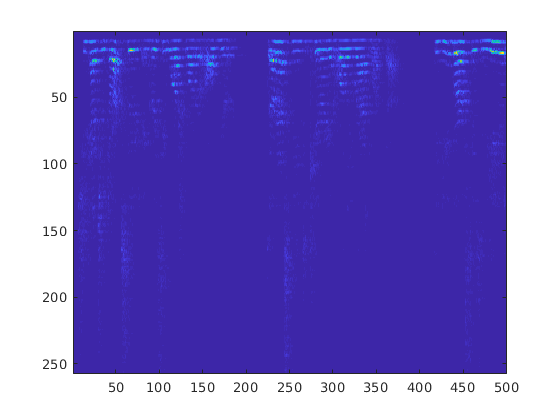

imagesc(afin1)

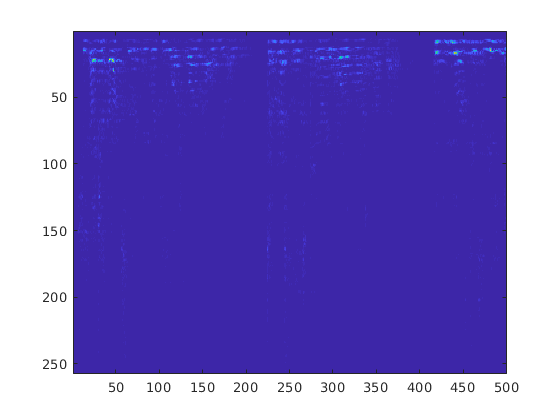

rebuild_fin1 = fin1(1:257, :)./abs(fin1(1:257, :)).*abs(dfin1);
diff = (abs(fin1(1:257, :))-abs(rebuild_fin1));
imagesc(abs(diff))

r = [rebuild_fin1(:, :); conj(rebuild_fin1(end-1:-1:2, :))];
sound1 = stftsynthesis(r', cfg.fft_size, cfg.shift);
player1 = audioplayer(sound1, fs);
play(player1)

sound2 = stftsynthesis(fin1', cfg.fft_size, cfg.shift);
player2 = audioplayer(sound2, fs);
play(player2)